% main_simulation.m
% 振动主动控制仿真主程序
% 支持三种模式：
%   MODE = 1 : 纯 FxLMS（用于收集训练数据）
%   MODE = 2 : 混合控制（加载预训练神经网络，固定 α=1）
%   MODE = 3 : 在线学习混合控制（OnlineNN + 自适应混合控制）

clear; clc; close all;

%% ==================== 用户配置 ====================
MODE = 3;   % 1:纯FxLMS(收集数据)  2:离线混合(固定α=1)  3:在线学习混合(自适应α)

% 仿真参数
fs = 10000;                 % 采样率 [Hz]
dt = 1/fs;                  % 时间步长 [s]
duration = 30;              % 仿真时长 [s]
n_samples = duration * fs;
t = (0:n_samples-1)' / fs;

% 振动工况
vib_freq = 100;             % 振动频率 [Hz] 仅固定模式启效
vib_amp = 5.0;              % 振动幅值 [m/s²]

% 控制器参数
L = 128;                    % FxLMS 滤波器阶数
mu_fixed = 5e-6;            % 固定步长
delta = 1e-6;               % 正则化参数（未使用归一化）

% 次级路径参数
delay = 4;                  % 延迟步数
s_hat_gain = -0.2;          % 次级路径增益（负号由脉冲测试确定）

% 神经网络参数
input_dim = 19;
hidden_dims = [128, 64];    % 在线网络结构（可调整）

% 数据收集（仅 MODE=1 时有效）
collect_interval = 5;      % 每5步记录一个样本

% 混合控制参数（MODE=2 或 3 时有效）
alpha_fixed = 1;            % MODE=2 时使用的固定混合系数
alpha_min = 0;
alpha_max = 0.15;           % MODE=3 时最大混合系数
performance_window = 100;   % 性能评估窗口

% 在线学习参数（仅 MODE=3 有效）
buffer_size = 1000;         % 经验缓冲区大小
update_interval = 150;      % 每多少步更新一次网络
batch_size = 32;            % 每次更新用的批量大小
train_epochs = 5;           % 每次更新的训练轮数
lr_online = 0.0005;         % 在线学习率（较小，避免遗忘）

%% ==================== 初始化物理模型 ====================
vib_source = VibrationSource();
vib_source.frequencies = vib_freq;
vib_source.amplitudes = vib_amp;
vib_source.phases = 0;
vib_source.noise_level = 0.05;

structure = StructuralDynamics(fs, 5, false);

负载 5.0 N: 目标平均阻尼比 = 0.0250
  各模态阻尼比: [0.0150, 0.0225, 0.0375]



actuator = PiezoActuator();

作动器状态已重置


actuator.K = 0.85;
actuator.fn = 3100;
actuator.zeta = 0.023;
actuator.alpha = 0.15;
actuator.beta = 0.035;
actuator.gamma = 0.025;

sensor = Accelerometer(fs);

加速度计初始化: PCB 352C33
  灵敏度: 98 mV/g
  带宽: 0.5-3000 Hz
  噪声密度: 6.0 μg/√Hz


sensor.sensitivity = 98;
sensor.bandwidth = [0.5, 3000];
sensor.noise_density = 6e-6;

%% ==================== 次级路径 ====================
fprintf('次级路径: 延迟 %d 步, 增益 %.2f\n', delay, s_hat_gain);

次级路径: 延迟 4 步, 增益 -0.20


s_hat = zeros(delay+1, 1);
s_hat(end) = s_hat_gain;

%% ==================== 控制器初始化 ====================
% FxLMS 结构
fxLMS = struct();
fxLMS.order = L;
fxLMS.w = zeros(L,1);
fxLMS.S_hat = s_hat(:);
buffer_len = max(L, length(s_hat));
fxLMS.x_buffer = zeros(buffer_len,1);
fxLMS.xf_buffer = zeros(L,1);

% 神经网络与混合控制器（根据模式初始化）
if MODE == 2
    % 离线预训练网络（需存在 trained_nn.mat）
    S = load('trained_nn.mat');
    if isfield(S, 'nn') && isa(S.nn, 'ResidualNN_Simple')
        nn = S.nn;
        fprintf('已加载预训练神经网络，类型：%s\n', class(nn));
    else
        error('trained_nn.mat 中未找到有效的 ResidualNN_Simple 对象');
    end
    hybrid = [];   % 模式2不使用自适应混合
elseif MODE == 3
    % 在线学习网络（随机初始化）
    online_nn = OnlineNN(input_dim, hidden_dims, buffer_size, update_interval, ...
                         batch_size, train_epochs, lr_online);
    fprintf('在线神经网络已初始化（随机权重）\n');
    % 自适应混合控制器
    hybrid = HybridController(alpha_min, alpha_max, performance_window);
    hybrid.verbose = true;
else
    nn = [];
    hybrid = [];
end

在线神经网络已初始化（随机权重）



%% ==================== 预分配数组 ====================
vibration_raw = zeros(n_samples,1);
control_signal = zeros(n_samples,1);
error_signal = zeros(n_samples,1);
y_linear = zeros(n_samples,1);
y_nn = zeros(n_samples,1);
alpha_history = zeros(n_samples,1);
mu_history = zeros(n_samples,1);
rms_history = zeros(n_samples,1);

% 数据收集（仅 MODE=1 时使用）
if MODE == 1
    data_collect = struct();
    data_collect.features = [];
    data_collect.targets = [];
end

%% ==================== 主仿真循环 ====================
acc_control = 0;   % 上一时刻控制产生的加速度
fprintf('开始仿真 (模式 %d)...\n', MODE);

开始仿真 (模式 3)...


tic;

for k = 1:n_samples
    % 原固定频率模式
    condition = struct('spindle_rpm', 3000, 'enable_noise', true, ...
        'enable_frequency_modulation', false, ...
        'enable_amplitude_modulation', false, ...
        'enable_random_shock', false);

    %condition.frequency_mode = 'fixed';   % 固定模式

    % 若要使用线性扫频模式
    % condition.frequency_mode = 'chirp';
    % condition.freq_start = 50;
    % condition.freq_end = 100;
    % condition.chirp_duration = duration;  % 扫频总时长

    % 若要使用正弦调制模式
    condition.frequency_mode = 'modulated';
    condition.freq_center = 75;      % 中心频率 75 Hz
    condition.freq_dev = 25;         % 偏移 ±25 Hz → 50~100 Hz
    condition.mod_freq = 0.5;        % 调制频率 0.5 Hz
    condition.amp = vib_amp;         % 幅值 5.0 m/s²（从外部变量传入）

    vibration_raw(k) = generate_vibration(vib_source, t(k), condition);
    
    % ---- 当前误差（原始振动 + 上一时刻控制效果） ----
    error_signal(k) = vibration_raw(k) + acc_control;
    
    % ---- 提取特征（用于神经网络） ----
    if k >= input_dim
        features = extract_features(vibration_raw, error_signal, control_signal, k, input_dim);
    else
        features = zeros(1, input_dim);
    end
    
    % ---- FxLMS 更新 ----
    if k >= L
        % 更新参考信号缓冲区
        fxLMS.x_buffer = [vibration_raw(k); fxLMS.x_buffer(1:end-1)];
        % 计算滤波参考信号
        xf = 0;
        M = length(fxLMS.S_hat);
        for j = 1:min(M, k)
            xf = xf + fxLMS.S_hat(j) * fxLMS.x_buffer(j);
        end
        fxLMS.xf_buffer = [xf; fxLMS.xf_buffer(1:end-1)];
        % 控制输出
        y_linear(k) = fxLMS.w' * fxLMS.x_buffer(1:L);
        % 系数更新
        fxLMS.w = fxLMS.w - mu_fixed * error_signal(k) * fxLMS.xf_buffer;
    else
        y_linear(k) = 0;
    end
    
    % ---- 神经网络补偿 ----
    if MODE == 2 && k >= input_dim
        % 离线网络
        y_nn(k) = nn.forward(features');
    elseif MODE == 3 && k >= input_dim
        % 在线网络：前向传播
        y_nn(k) = online_nn.forward(features);
        % 计算残差并存储经验
        residual = error_signal(k) - y_linear(k);
        online_nn.store_experience(features, residual);
    else
        y_nn(k) = 0;
    end
    
    % ---- 混合控制输出 ----
    switch MODE
        case 1   % 纯 FxLMS
            y_total = y_linear(k);
            
        case 2   % 离线混合控制，固定 α=1（可调整缩放）
            scale = 0.08;   % 与训练时缩放因子匹配（可根据需要调整）
            y_total = y_linear(k) + scale * y_nn(k);
            
        case 3   % 在线学习 + 自适应混合控制
            alpha = hybrid.alpha;   % 当前混合系数
            y_total = y_linear(k) + alpha * y_nn(k);
            alpha_history(k) = alpha;
    end
    % 限幅
    y_total = max(min(y_total, 10), -10);
    control_signal(k) = y_total;
    
    % ---- 执行控制，获取结构响应 ----
    [~, actuator_force] = actuator.actuate(control_signal(k), dt);
    [~, ~] = structure.respond(actuator_force, dt);
    acc_control = structure.get_acceleration(2);   % 传感器位置加速度
    
    % ---- 自适应混合系数更新（仅 MODE=3） ----
    if MODE == 3
        hybrid.adapt_alpha(error_signal(k), vibration_raw(k));
    end
    
    % ---- 数据收集（仅 MODE=1） ----
    if MODE == 1 && k >= input_dim && k > 2000 && mod(k, collect_interval) == 0
        scale = 5;
        target = (error_signal(k) - y_linear(k)) / scale;
        data_collect.features(end+1, :) = features;
        data_collect.targets(end+1) = target;
    end
    
    % ---- 滑动 RMS（用于监控） ----
    window = 100;
    if k >= window
        rms_history(k) = rms(error_signal(k-window+1:k));
    end
    
    % ---- 进度显示 ----
    if mod(k, floor(n_samples/10)) == 0
        if MODE == 3
            fprintf('进度: %.0f%%, RMS误差: %.3f, alpha: %.3f\n', ...
                100*k/n_samples, rms_history(k), hybrid.alpha);
        else
            fprintf('进度: %.0f%%, RMS误差: %.3f\n', 100*k/n_samples, rms_history(k));
        end
    end
    
    % ---- 可选：打印前200步调试信息 ----
    %if k <= 200
        %if MODE == 1
            %fprintf('k=%d, err=%.3f, y_lin=%.3f, norm(w)=%.3e, xf1=%.3f\n', ...
                %k, error_signal(k), y_linear(k), norm(fxLMS.w), fxLMS.xf_buffer(1));
        %elseif MODE == 2
            %fprintf('k=%d, y_lin=%.3f, y_nn=%.3f, err=%.3f\n', k, y_linear(k), y_nn(k), error_signal(k));
        %elseif MODE == 3
            %fprintf('k=%d, y_lin=%.3f, y_nn=%.3f, err=%.3f, alpha=%.3f\n', ...
                %k, y_linear(k), y_nn(k), error_signal(k), hybrid.alpha);
        %end
    %end
end

基准性能已记录: RMS = 0.0006
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 10%, RMS误差: 0.144, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 20%, RMS误差: 0.162, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 30%, RMS误差: 0.130, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 40%, RMS误差: 0.115, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 50%, RMS误差: 0.148, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 60%, RMS误差: 0.136, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 70%, RMS误差: 0.155, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 80%, RMS误差: 0.118, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 90%, RMS误差: 0.153, alpha: 0.075


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


状态切换: hybrid_trial -> pure_linear
状态切换: pure_linear -> hybrid_trial


features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]
features size: [32, 19]
y_linear size: [32, 1]
y_target size: [32, 1]
输入维度: X size = [19, 32], T size = [1, 32]


进度: 100%, RMS误差: 0.178, alpha: 0.075



sim_time = toc;
fprintf('仿真完成，耗时 %.2f 秒\n', sim_time);

仿真完成，耗时 34.90 秒



%% ==================== 性能评估 ====================
fprintf('\n=== 性能评估 ===\n');


=== 性能评估 ===


rms_error = rms(error_signal);
peak_error = max(abs(error_signal));
convergence_idx = find(abs(error_signal) < 0.1 * rms_error, 1);
if ~isempty(convergence_idx)
    convergence_time = convergence_idx / fs;
else
    convergence_time = NaN;
end
fprintf('RMS误差: %.4f m/s²\n', rms_error);

RMS误差: 0.3266 m/s²


fprintf('峰值误差: %.4f m/s²\n', peak_error);

峰值误差: 5.0630 m/s²


fprintf('收敛时间: %.2f s\n', convergence_time);

收敛时间: 0.00 s



% 频域指标
[Pv, f] = pwelch(vibration_raw, hamming(512), 256, 512, fs);
[Pe, ~] = pwelch(error_signal, hamming(512), 256, 512, fs);
total_reduction = 10*log10(sum(Pv)/sum(Pe));
fprintf('总振动抑制比: %.1f dB\n', total_reduction);

总振动抑制比: 20.9 dB


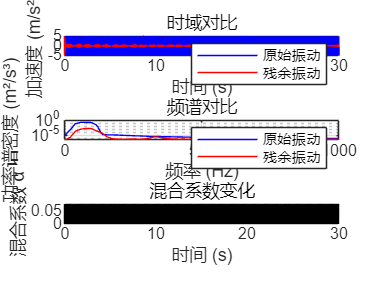


%% ==================== 绘图 ====================
figure;
subplot(3,1,1);
plot(t, vibration_raw, 'b', t, error_signal, 'r');
xlabel('时间 (s)'); ylabel('加速度 (m/s²)');
legend('原始振动', '残余振动'); title('时域对比'); grid on;

subplot(3,1,2);
semilogy(f, Pv, 'b', f, Pe, 'r');
xlabel('频率 (Hz)'); ylabel('功率谱密度 (m²/s³)');
legend('原始振动', '残余振动'); title('频谱对比'); xlim([0,1000]); grid on;

subplot(3,1,3);
if MODE == 3
    plot(t, alpha_history, 'k');
    xlabel('时间 (s)'); ylabel('混合系数 α'); title('混合系数变化'); grid on;
else
    axis off;
end

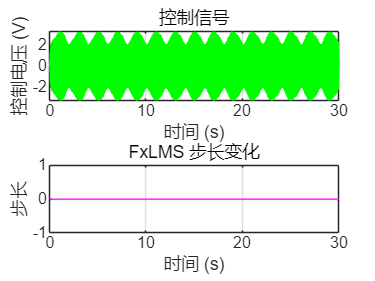


figure;
subplot(2,1,1);
plot(t, control_signal, 'g');
xlabel('时间 (s)'); ylabel('控制电压 (V)'); title('控制信号'); grid on;
subplot(2,1,2);
plot(t, mu_history, 'm');
xlabel('时间 (s)'); ylabel('步长'); title('FxLMS 步长变化'); grid on;


%% ==================== 保存结果 ====================
save('simulation_results.mat', 't', 'vibration_raw', 'error_signal', ...
     'control_signal', 'alpha_history', 'rms_history', ...
     'rms_error', 'peak_error', 'convergence_time', 'total_reduction');

if MODE == 1
    save('training_data.mat', 'data_collect');
    fprintf('训练数据已保存至 training_data.mat，共 %d 个样本\n', size(data_collect.features,1));
end